# 2PEM-100A

## `PRACTICE 2_1`

## `Uploading and analyzing energy consumption data`

`More information:`

- [https://2pem100a.blogspot.com/](https://2pem100a.blogspot.com/)

`More examples:`

- [https://github.com/vasanza/Matlab_Code/tree/Electrical-Systems-Simulation](https://github.com/vasanza/Matlab_Code/tree/Electrical-Systems-Simulation)

- [https://github.com/avbazurt/Simulacion_Sistemas_Electricos](https://github.com/avbazurt/Simulacion_Sistemas_Electricos)

`Dataset:`

- [http://ieee-dataport.org/8630](http://ieee-dataport.org/8630)

Technical information

- Sampling frequency: 4Hz (250mSeg)

# **Example 1: Loading a .mat file**

clear;clc;
path=fullfile('./dataset.mat');
data=load(path);
data=struct2cell(data);
data=data{1,1};
data=table2array(data(:,4:12));
data1=data(1:1000,:);

# **Example 2: Statistical information of the data**

max(data)

ans =   120.2000    1.9800  226.6000   60.1000  100.1200    1.0000   38.3300   99.8000   55.2000


min(data)

ans =   119.4000    0.7000   79.1000   59.7000   48.5600    0.7300   28.3300         0         0


datastats(data(:,1))

ans = struct with fields:
       num: 1625175
       max: 120.2000
       min: 119.4000
      mean: 120.0236
    median: 120
     range: 0.8000
       std: 0.0648


# **Example 3: Graphing data**

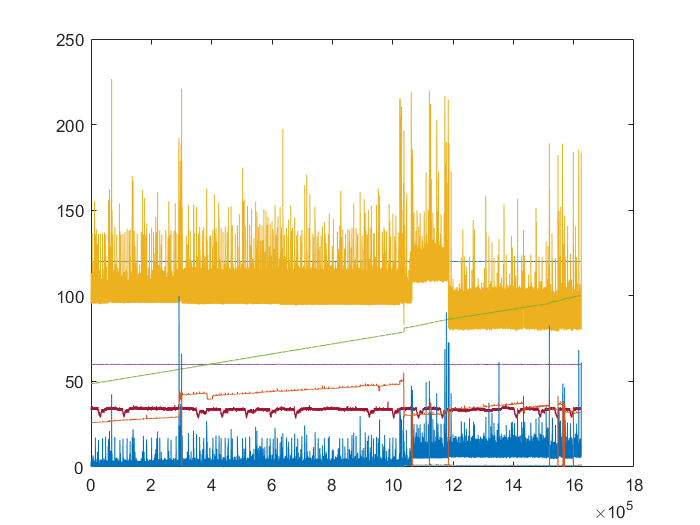

plot(data)